# Phase Portrait

close all; clc

% find equilibrium points
syms a positive
syms b nonzero
syms x1 x2

% find equilibrium points
f1 = -x1 + 2*x1^3 + x2;
f2 = -x1 - x2;

sln = solve([f1==0, f2==0], [x1 x2]);
sln.x1

$$ans = \left(\begin{array}{c} 0\\ 1\\ -1 \end{array}\right)$$

sln.x2

$$ans = \left(\begin{array}{c} 0\\ -1\\ 1 \end{array}\right)$$

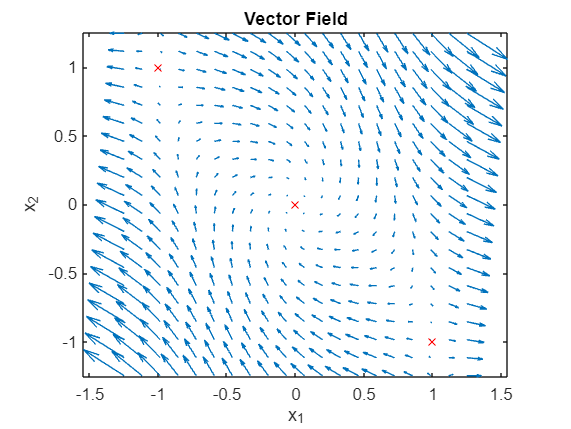


% Create vector field
x = linspace(-1.25,1.25,20);
y = linspace(-1.25,1.25,20);
[X,Y] = meshgrid(x,y);

DX = -X + 2*X.^3 + Y;                 
DY = -X - Y;

quiver(X,Y,DX,DY,2);
xlabel('x_1')
ylabel('x_2')
axis tight equal;
title("Vector Field")

% draws x's on the equilibrium points
hold on;
for i=1:numel(sln.x1)
    plot(sln.x1(i), sln.x2(i), 'rx')
end
hold off